% im = imread("tinyheart.PNG");
% img = rgb2gray(im);
% sigma = 1;
% noise = randn(size(img)).*sigma;
% imshow(noise);

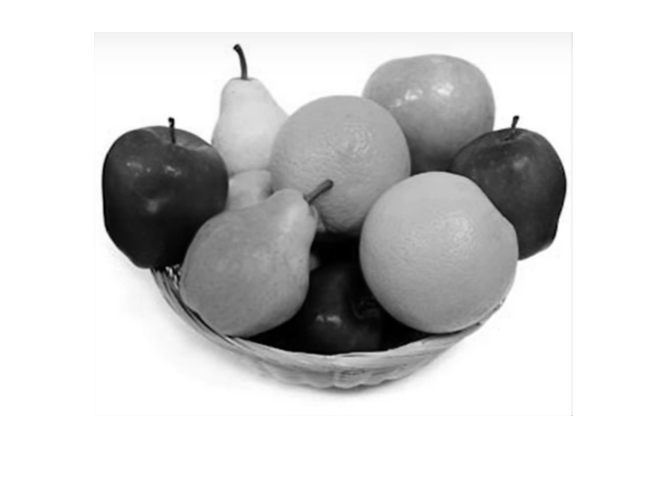

im = imread("fruits.PNG");
img = rgb2gray(im);
imshow(img);

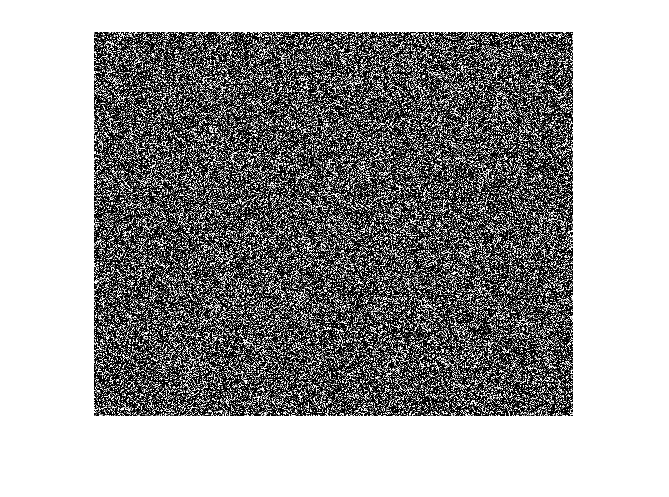

noise1 = randn(size(img));
noise2 = randn(size(img)).*2;
noise3 = randn(size(img)).*10;
imshow(noise1);

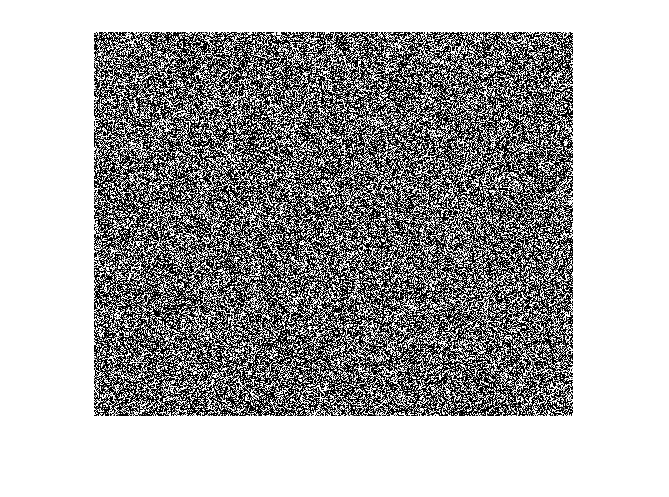

imshow(noise2);

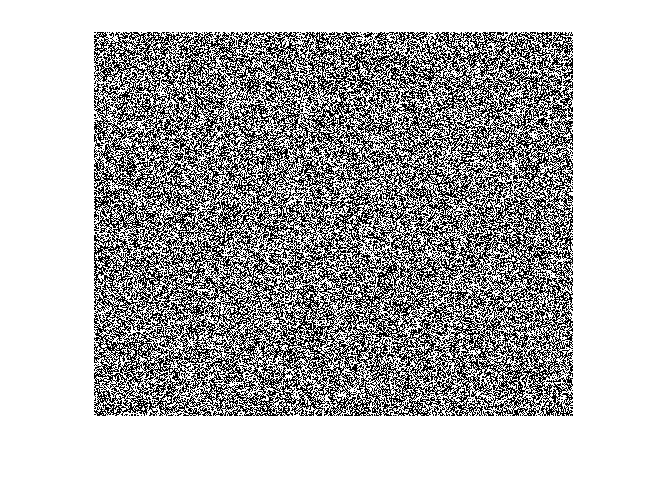

imshow(noise3);



class(img)

ans = 'uint8'

class(noise1)

ans = 'double'


output1 = double(img) + noise3; 
[min, max] = minmax(img)

min = uint8
0

max = uint8
255

[min, max] = minmax(double(img))

min = 0

max = 255

[min, max] = minmax(noise1)

min = -4.3063

max = 4.5454

[min, max] = minmax(noise2)

min = -8.4324

max = 8.4547

[min, max] = minmax(noise3)

min = -43.3772

max = 45.1370

[min, max] = minmax(output1)

min = -31.4663

max = 297.1765

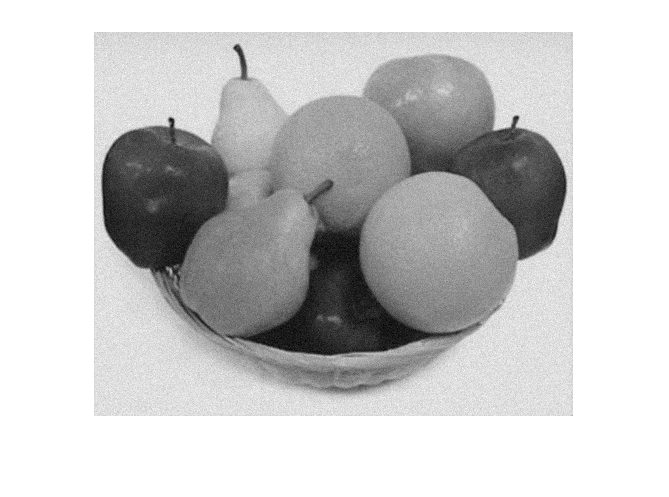

imshow(output1,[]);

Key learnings : 

### randn 

`X = randn` returns a random scalar drawn from the standard normal distribution.

`X = randn(`[`n`](https://in.mathworks.com/help/matlab/ref/randn.html#bufqhx9-n)`)` returns an `n`-by-`n` matrix of normally distributed random numbers.

The **standard normal distribution** is a special case of the **normal distribution**. It is the **distribution** that occurs when a **normal** random variable has a mean of zero and a **standard** deviation of one.

noise range with sigma as 1 is [-4.3068, 4.5454] 

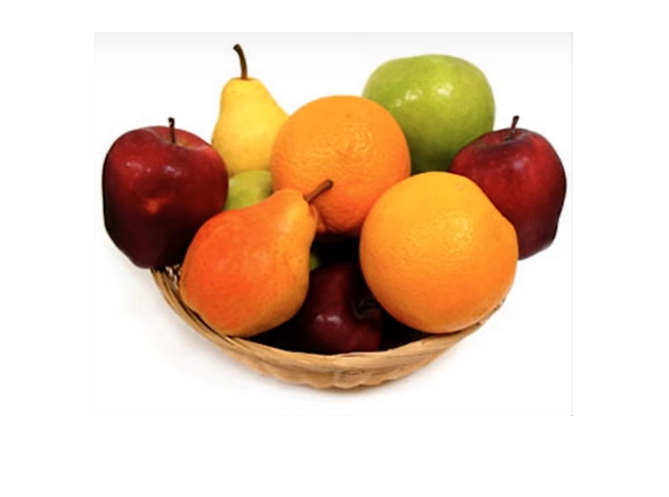

im1 = imread("fruits.PNG");
imshow(im1,[]);

double(im1)

ans = ans(:,:,1) =

   237   241   241   240   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241  

imshow(double(im1)) shows a whitish image why ? 

[https://in.mathworks.com/matlabcentral/answers/88934-images-don-t-show-with-imshow-after-converting-them-to-double](https://in.mathworks.com/matlabcentral/answers/88934-images-don-t-show-with-imshow-after-converting-them-to-double)

MATLAB looks at the datatype to decide which range of values to expect. uint8 are expected to be 0 to 255. double are expected to be 0 to 1. When you double() a uint8 you end up with 0. to 255. and everyt value from 1 upwards will be considered to saturate the maximum 9 to 1 range.

You im2double() instead of double()

I wouldn't use im2double. It's usually inconvenient to scale your image when you want to do some operations, like convolution or whatever.  **All you need to do is to simply use []** in imshow():

`imshow(yourDoubleImage, []);`

and it will work beautifully for gray scale images. If it's a color image though, that won't work, you'd have to case to uint8 to display or use im2double and, unfortunately, have to deal with altered intensity values. I prefer the casting to uint8 which usually works if your values remain in the range of about 0-255. Step through this demo and it will illustrate the different things that happen depending on what you do.

imshow(im2double(im1));

im2 = im1(:,:,3);
noise1 = randn(size(im1));
noise2 = randn(size(im2)).*20;
% noise(:,:,2)
% class(noise)
% size(noise)
out1 = im2double(im1) + noise1;
disp(class(out1));

double


disp(size(out1));

   384   479     3



% im1(:,:,1)

ans = 384×479 uint8 matrix
   237   241   241   240   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241
   239   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242
   239   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243
   239   243   243   243   243   243   243   243   243   243   243   2

% im1(:,:,2)

ans = 384×479 uint8 matrix
   237   241   241   240   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241
   239   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242
   239   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243
   239   243   243   243   243   243   243   243   243   243   243   2

% im1(:,:,3)

ans = 384×479 uint8 matrix
   237   241   241   240   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241   241
   239   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242   242
   239   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243   243
   239   243   243   243   243   243   243   243   243   243   243   2

% out1(:,:,1)

ans =     1.4431    0.2554    3.4231    1.2244    0.8455    0.0270    1.9551    1.8939   -0.2880    0.4060    0.9208    0.4971    0.2345    0.3740    1.1561    3.2714    0.1467    1.3132    2.8793    0.7627    1.8743   -0.9138   -0.2562    0.8666    1.0441    1.3319    0.2451   -0.3835    1.6464    0.8420    1.9301    1.4664   -0.5253    2.9804   -0.4038    0.9762    1.6526   -0.0192    0.8381    1.1743    1.6587    2.5778    1.5935   -0.1780    0.6593   -1.4264    0.2164    1.4150    0.8316    1.1334
    0.7972    3.1029    0.8506    2.0395    0.4328    1.2238   -0.4312    2.5441    1.2749    1.8061   -1.4206   -0.1723    4.1629    1.3817    0.2550    2.3483    1.5788    1.1070    1.6319    1.5583    0.9900    1.0193    1.3794   -0.4502    0.6229    1.8042    0.3261   -1.6379    0.3700   -0.4892   -0.0390    0.1584    0.1353    2.9020    1.5094    0.7574   -0.3490    1.6187    2.1992    1.2853    2.2180   -0.9174    2.6805   -0.4770   -0.4738    0.6355   -0.0789    1.2969    1.3207   

% out1(:,:,2)

ans =     2.4198    0.7915    0.4607    1.2191   -0.7396   -1.8459    1.0010   -0.7203    0.5762    0.7350    1.1142    1.2487    0.4061    0.5521    1.5811    1.7906    2.1168    1.2364    2.6094    1.4564    1.1462    0.9450    1.0562    1.3894    1.3572    0.2845    2.1738    1.2606   -0.1258    3.1413    1.8503    0.1302    1.6091    1.1008    0.0461    1.2939    0.7118   -0.3790    0.3676    2.0881    1.6711   -0.5244    1.6389    1.6870    1.5560    0.5639    0.1177    0.2612    0.8854    0.3940
    1.3821   -0.9853    0.8990    2.7123    0.4831    0.0273    1.5705    1.3827    1.2631    1.6013   -0.7230    1.4224    1.6531    0.2756    0.6222    0.6914    1.3163    0.5120    0.2318    0.4439    0.7034    0.7727    2.2276    0.4222    0.7056    1.9538    1.2883    1.8890    0.7605    0.6803    0.0254    0.1451   -0.1814    0.1096    1.0681    2.8557    0.4191    1.5744    0.3850    0.0037    0.5687    1.0968    0.2340    0.1081    0.8615    2.0199    0.9841    2.1546    0.6561   

% out1(:,:,3)

ans =     0.3860   -0.1761    0.8508   -0.5702    0.8647    0.3401    0.8069    1.6422    1.1274   -0.0924    1.3625    1.4723    0.7858    1.5307    2.4155    2.6935   -0.9413    0.0303    0.9572    1.4672    1.2059    1.4165    1.1935    0.5748    2.1820    2.4594   -0.1249    0.9384    0.3354    1.7941    1.3581    1.9912    2.6076    0.3283   -0.4506    2.7782   -0.3310    2.6495    2.1815    1.2400    0.4802    0.8347    0.7954    1.5604    1.1724    2.1051    1.4381    0.4737    1.4029    0.2255
   -0.7708    0.0954    0.5984    2.4653    0.1465   -0.1179    0.4871    1.1074    0.9690    2.1455    0.3448    1.2216   -0.5939    0.3411    1.0347    1.9426   -0.4514    1.1785    3.1633    2.4031    1.9073    1.9644    1.5884   -0.7000    1.8726    0.3488    1.5126    2.5419    0.2744    2.1196    0.6601    0.6969    0.7592    0.8294    0.9858   -0.0368   -0.6889    0.2588    0.2318    1.2664    1.9350    1.1812    1.1013    0.3310    0.9526    1.6502    0.8833    0.9025    2.6756   

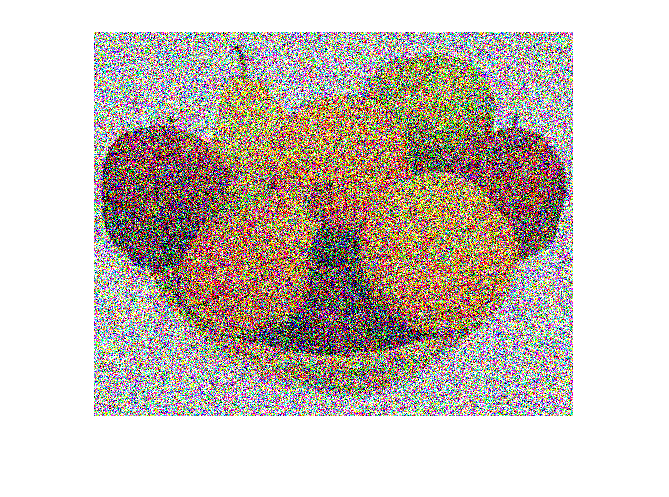

imshow(out1,[]);

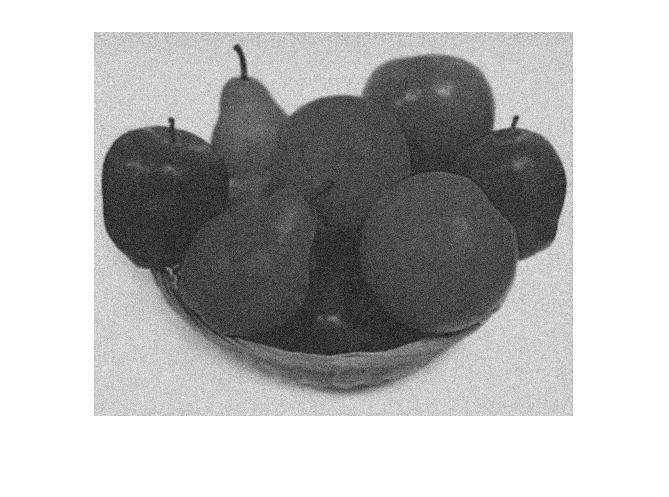

out2 = double(im2) + noise2;
imshow(out2,[]);